# МЕТОДЫ ОПТИМИЗАЦИИ

## Семинар 11. Метод градиентного поиска

#### Немного векторного анализа

Вектор  - это не столбик чисел, а сумма базисных векторов

  
$$\vec{a}=a_1\hat{e}_1+...+a_N\hat{e}_N$$


$\hat{e}_i$ - базисный вектор (для простоты будем считать, что все базисыные вектора взаимоортогональны и имеют единичную длину)

Строго говоря плюсик при суммировании векторов - это не тот же плюсик, что при суммировании чисел, но обычно используют тот же значок.

Координаты вектора:

$a_i=\hat{e}_i\cdot\vec{a}=\hat{e}_i\cdot\sum_j a_j\hat{e}_j=a_i$ так как $\hat{e}_i\cdot\hat{e}_j=0 $ если $j\neq i$

Диада - два вектора:

$\overleftrightarrow {d}=\vec{a}\otimes \vec{b}=\vec{a}\vec{b}$, $\otimes$ - тензорное произведение, в отличие от скалярного произведения и обычного произведени чисел оно некоммутативно, в остальном ведет себя также как скалярное произведение.

Вектора могут принадлежать разным векторным пространствам.

Диады можно скалярно умножать на вектор слева и справа, при этом из пары векторов диады умножается тот вектор, который стоит ближе


$$\overleftrightarrow {d}\cdot \vec{c}=\vec{a}\vec{b}\cdot \vec{c}$$
 

Правый вектор диады и вектор на который умножаем справа должны принадлежать одному и тому же пространству:


$$\overleftrightarrow {d}\cdot \vec{c}=\vec{a}(\sum_ib_i\hat{u}_i)\cdot(\sum_i c_i\hat{u}_i)=\vec{a}\sum b_ic_i$$


, это похоже на $\vec{a}\vec{b}^T\vec{c}$


$$\vec{a}=a_1\hat{e}_1+...+a_N\hat{e}_N$$



$$\vec{b}=b_1\hat{u}_1+...+b_M\hat{u}_M$$



$$\overleftrightarrow {d}=\vec{a}\vec{b}=\sum_{i=1}^N\sum_{j=1}^Ma_ib_j\hat{e}_i\hat{u}_j$$


Координаты диады можно сложить в таблицу, которая называется матрицей, номер строки будет соответствовать индексу базисного вектора "левого" пространства (пространство столбцов), а индекс столбца - индексу базисного вектора "правого" пространства (пространство строк):

clearvars
a= sym("a",[3,1])
b = sym("b",[2 1],"real")
a*b'

Сумму диад называют  диадиком.

Теперь, допустим у нас есть матрица $A=[\vec{a}_1 \dots \vec{a}_j \dots \vec{a}_m]$ , состоящая из столбцов $\vec{a}_j$, ее содержимое - это координаты диадика:


$$\overleftrightarrow {A}=\vec{a}_1\hat{u}_1+\dots \vec{a}_i\hat{u}_j+\dots \vec{a}_m\hat{u}_m$$


То есть, это сумма диад,  $\hat{u}_i$ - базисные вектора пространства строк. Каждый из вектор-столбцов, в свою очередь, это линейная комбинация базисных векторов пространства столбцов: $\vec{a}_j=\sum_{j=1}^na_{ij}\hat{e}_i$, соотвественно матрица $A$ - это координаты диадика состоящего из $m\times n$ диад. Диада $\overleftrightarrow {A}$ действует на вектор, принадлежащий пространству строк (базис  $\hat{e}_i$), соотвественно:

 
$$\overleftrightarrow {A}\cdot \vec{c}=\vec{a}(\sum_ib_i\hat{u}_i)\cdot(\sum_i c_i\hat{u}_i)=\vec{a}\sum b_ic_i$$


Матрица  - форма записи координат диадиков (суммы диад)


$$\overleftrightarrow {B}=\vec{b}_1\hat{u}_1+\dots+\vec{b}_m\hat{u}_m$$


#### Задача метода наименьших вадратов в диадной форме

В качестве упражнения сформулируем задачу линейной регрессии в диадной форме.

Задача линейной регрессии состоит в том, чтобы найти такой вектор параметров $\vec{b}$, который минимизирует скалярную функция невязки $\Phi(\vec{b})$ модуль вектора ошибки:


$$argmin(\Phi(\vec{b})) \ где\ \Phi(\vec{b})= ||\vec{r}||^2$$


Вектор $\vec{r}$ - это разница между предсказанием нашей линейной модели ($X\vec{b}$) и экспериментально наблюдаемым вектором $\vec{y}$.

Раньше мы записывали невязку так:


$$\Phi(\vec{b})= \vec{r}^T\vec{r}=||X\vec{b}-\vec{y}||^2 = (X\vec{b}-\vec{y})^T( X\vec{b}-\vec{y}) $$


В тензорной записи она будет выглядеть так:


$$\Phi(\vec{b})= \vec{r}\cdot\vec{r}=|| \overleftrightarrow {X}\cdot \vec{b}-\vec{y}||^2 = (\overleftrightarrow {X} \cdot\vec{b}-\vec{y})\cdot( \overleftrightarrow {X}\cdot\vec{b}-\vec{y}) $$


$X<=> \overleftrightarrow {X}=\sum_{ij}x_{ij}\hat{e}_i\hat{u}_j$  - диада предикторов


$$\vec{y}=\sum_i y_i\hat{e}_i, \vec{b}=\sum_k b_k\hat{u}_k$$


$\hat{e}_i$  - базисные вектора пространства столбцов  - то есть, это то пространство, в котором "живут"  вектора размером с вектор наших измеренных точек, в этом пространстве живут столбцы матрицы предикторов, вектор экспериментальных точек

 $\hat{u}_j$ - базисные вектора пространства строк  - то есть, это то пространство, в котором живут вектора размером с вектор коэффициентов, в этом пространстве живет вектор $\vec{b}$

### Оператор градиента

Дифференциальный оператор градиента:


$$\nabla=\sum_i\hat{x}_i\frac {\partial}{\partial x_i}$$


$f(\vec{x})$ - скалярная функция векторного аргумента, где $\vec{x} \in R^n$ - вектор переменных оптимизации.

тогда градиент этой функции в пространстве $R^n$ имеет вид :


$$\nabla f(\vec{x})=\matrix {\frac{\partial f}{\partial x_1} \cr \vdots \cr \frac{\partial f}{\partial x_n} }$$


Градиент   -  это вектор  в пространстве $R^n$, который указывает в сторону наибольшего возрастания функции $f(\vec{x})$ . 

Основные свойства оператора градиента:


$$\nabla(f(\vec{x})g(\vec{x}))=g\nabla f + f\nabla g$$


Градиент вектора:


$$\vec{r}(\vec{x})=r_1(\vec{x})\hat{e}_1 + .... +r_n(\vec{x})\hat{e}_n$$


То есть, $r_i(\vec{x})$ - это некоторые скалярные функции векторного аргумента, тот факт, что вектор $\vec{x}$ и вектор $\vec{r}$ принадлежат разным векторным пространствам нас не смущает. Также мы предполагаем, что базисные вектора $\hat{e}_i$ не зависят от $\vec{x}$. Базисные вектора пространства вектора $\vec{x}$ это $\hat{x}_1, \dots, \hat{x}_n$

#### Градиент вектора

В соотвествии с формулой:


$$\nabla\vec{r}=\sum_{i,j} \frac {\partial r_j}{\partial x_i}\hat{x}_i\hat{e}_j$$


Это матрица Якоби.

Отсюда легко видеть, что, если скалярная функция векторного аргумента представляет собой скалярное произведение некоторых векторов $f=\vec{a}\cdot\vec{b}$, то:


$$\nabla f=(\nabla \vec{a})\cdot \vec{b} + \vec{a} \cdot (\nabla \vec{b})$$


В частности градиент модуля некоторого вектора будет:


$$\nabla(\vec{r}\cdot\vec{r})=2((\nabla\vec{r})\cdot\vec{r})$$


#### Реализация алгоритма численного расчета градиента скалярной функции

Функция численного расчета для расчета градиента скалярной функции векторного аргумента может иметь следующий код:

Функция **num_grad** находится в файле **num_grad.m, **в той же папке, что и данный скрипт. Отличие от функции расчета производной, которая вводилась ранее, в том, что для расчета градиента мы варьируем отдельно каждую из координат (частная производная), которые затем складываем в один вектор (градиент скалярной функции).

#### Простая скалярная функция векторного аргумента - квадратичная форма

Рассмотрим поведение квадратичной формы (скалярная функция векторного аргумента):

$F(\vec{x})=\vec{x}^TA\vec{x}$ , где $A$ - некоторая матрица произвольная

Когда $F(\vec{x})>0$ для любого $\vec{x}$ матрица называется $A$положительно-определенной. 

Как связана положительная определенность и форма кривой?

Далее будем строить скалярную кривую в виде трехмерной поверхности и в виде контурного изображения. Вектор $\vec{x}$ будет у нас двумерным, его координаты  - это координаты  в плоскости X,Y, то есть $\vec{x}=[\matrix{X \cr Y}]$. Для точки трехмерной поверхности, координата Z   - это значение функции $Z=F([\matrix{X \cr Y}])$, где X,Y - ее координаты. Для контурного изображения, значению Z соотвествует цвет контура, линии контура показывают области постоянного значения функции $F$. Градиент (двумерный вектор, как и вектор $\vec{x}$ ) на картинках показан стрелочками, стрелочки указывают в направлении градиента, длина стрелочки пропорциональна длине вектора градиента.

cd(get_folder())
clearvars
a11 = 5.93;
a12 = -2.33;
a21 = 2.3;
a22 = -3.6;
A = [a11,a12;a21,a22]
make_positive=false;
if make_positive
    A = A'*A % эта операция делает матрицу положительно определенной
end
% проверка на то, является ли матрица А положительно определенной, зачем?
if ~make_positive
    if isequal(A',A) % проверка является ли матрица симметричной
        check_A=A;
    else % матрица не симметрична
        check_A = (A' + A)/2;      
    end
    try chol(check_A) % пробуем разложение холецкого (если матрица не ПО то ошибка)
         disp('Матрица А положительно определенная')
    catch ME
         disp('Матрица А не положительно определенная')
    end
end
f = @(x) x(:)'*A*x(:); % функция - квадратичная форма
df = @(x) num_grad(f,x); % функция численного расчета градиента (возвращает вектор)
df_abs = @(x) norm(df(x));% функция расчета модуля градиента

ax = get_next_ax();
fsurf(@(x,y) f([x;y]),[-1,1]) % функции fsurf и fcontour строят поверхность и контур
% функции, которая принимает два скалярных аргумента
hold(ax,"on")
fcontour(ax,@(x,y) f([x;y]),[-1,1])
hold(ax,"off")

% теперь построим градиент 
spacing = 0.2;
[X,Y] = meshgrid(-1:spacing:1,-1:spacing:1);
U = X;V=X;F_value=X;G_module = X;

for ii =1:size(X,1)
    for jj=1:size(Y,2)
        x = X(ii,jj);y = Y(ii,jj);
        G_value = df([x;y]);
        F_value(ii,jj) = f([x;y]);
        G_module(ii,jj) = sqrt(G_value'*G_value);
        U(ii,jj) = G_value(1);
        V(ii,jj) = G_value(2);
    end
end
hold(ax,"on")
q = quiver(ax,X,Y,U,V);
hold(ax,"off")
% тоже самое, только на плоскости
ax = get_next_ax();
contour(ax,X,Y,F_value);
hold(ax,"on")
quiver(ax,X,Y,U,V)
hold(ax,"off")

Обратите внимание на область нулевого градиента (область где стрелочки становятся сосем короткими), как она связана с формой кривой поверхности ?

Также следует обратить внимание, что вектор градиента перпендикулярен изолиниям.

#### Итерационная оптимизация

Общая идея итерационной оптимизации состоит в том, чтобы "двигаться" в пространстве параметров оптимизации по шажкам, положение точки на $i$- м шаге итерации определяется вектором  $\vec{x}_{i}$. Таким образом, идея итрационной оптимизации состоит в том, чтобы из текущего положения $\vec{x}_{i}$ перейти в новую точку $\vec{x}_{i+1}$, которая будет ближе к точке локального минимума $\vec{x}^*$:


$$\vec{x}_{i+1} = \vec{x}_{i} +\vec{p}(\vec{x}_{i}\dots)$$


Вектор $\vec{p}(\vec{x}_{i}\dots)$ - это шаг итерации, собственно, задача алгоритма и состоит в том, чтобы рассчитать величину этого шага.  В самом простом случае шаг рассчитывается на основе координат текущей точки, но может использовать и данные о предыдущих точках ( $\vec{p}(\vec{x}_{i},\vec{x}_{i-1},\vec{x}_{i-2} \dots )$), например, как в методе сопряженных градиентов. Также сущесвую алгоритмы, которые на кажой итерации рассчитывают не одну а несколько точек. В этом случае алгоритм сожет использовать данные о других точках, которые "существуют" в пространстве одновременной с ним. Примероми таких алгоритмом могут служить метод Нелдера-Мида, эволюционный алгоритмы (particle swarm, genetic, simulated annealing  и др.)

#### Градиентная итерационная оптимизация

Градиентный оптимизатор - это итерационный алгоритм, который "движется" в пространстве параметров оптимизации от точке к точке, так что на кадом шаге итерации  направление вектора перехода от точки к точки противоположно направлению градиента (то есть, направлению максимального возрастания функции). Поэтому ($i+1$) координата в пространстве  $R^n$ выражается через предыдущую точку и градиент функции в виде:

$\vec{x}_{i+1} = \vec{x}_{i} -\mu \hat{g}(\vec{x}_{i}) ,\ где \  \hat{g}(\vec{x}_{i})= \frac {\nabla f(\vec{x}_i)}{||\nabla f(\vec{x}_i)||}$,

$\mu$- скалярный параметры алгоритма (длина шага), который пока фиксирован, вектор  $\hat{g}(\vec{x}_{i})$ - это вектор единичной длины вдоль градиента, таким образом, мы  оставляем от градиента только его направление, длину шага определяет параметр $\mu$. Этот параметр также называют "learning rate", потому, что он определяет скорость обучения модели.

Код простого оптимизатора показан ниже:

     Данный алгоритм очень прост, в цикле мы на каждой итерации рассчитываем градиент, нормируем его, оставляя только направление, и движемся вдоль градиента с простоянным шагом (**mu**). Критерием остановки цикла является либо достижение максимального числа итераций, либо когда изменение значения функции (Fval, Fval_previous), либо модуль шага переменных оптимизации (x,x_previous)   для двух последовательных итераций меньше некоторого заданного значения  (**tol**). 

    Следует отметить, что функция ***num_grad,*** в отличие от*** grad_search ***не имеет блока ***arguments...end***, это связано с тем, что так как она является частью итерационного алгоритма ее вызов производится большое количество раз, поэтому она не имеет функций для валидации аргументов. В данном случае мы следуем общему правилу выполнять проверки "на входе", то есть там, где происходит взаимодействие с "внешним миром". В данном случае входом являются входные аргументы функции  ***grad_search*****. **Так как наш оптимизатор универсальный, хочется, чтобы он работал с любыми входными функциями, мы четко определяем типы входных аргументов, а также присваиваем значения по умолчанию для опциональных аргументов. 

#### Оптимизация скалярной функции скалярного аргумента

Посмотрим как можно применять данные функции, вначале для одномерного поиска минимума скалярной функции:

addpath(get_folder());
F = @(x)sin(x); % ищем минимум данной функции
gradF = @(X) num_grad(F,X) % численный расчет градиента (функция численного расчета градиента имеет два входных аргумента, в данном случае при создании анонимной функции
% gradF, мы передаем первый аргумент num_grad  - собственно функцию, мы
% передаем как параметр, то есть она хранится в workspace данной анонимной
% функции
[xval,fval,iternumber,outflag]=grad_search(2,F,gradF,"mu",0.01)
xval/pi

Можно поиграться с входными опциональными аргументами grad_search: **mu, N, tol**

#### Оптимизация скалярной функции векторного аргумента

Теперь решим задачу векторной оптимизации - будем минимизировать квадратичную невязку между измеренными значениями и рассчитанными:


$$F(\vec{x})= \Sigma_k (y_i - f_i(\vec{x}))^2$$


$f_i(\vec{x})=x_1+x_2t_i$, где $t_i = [0:10]$

$y_i$ - "экспериментальные точки" дискретный набор точек, который мы хотим "зафитить" функцией $f(\vec{x},t)$, данная функция зависит от двух переменных оптимизации и рассчитывается для каждого знаечния независимой координаты $t_i$, скалярная функция $F(\vec{x})$ - скалярная функция  - квадратичная невязка (сумма квадратов расхождений между измеренными значениями и рассчитываемыми).

x_true =[7.11; 1]; % вектор истинных значений параметров 
t = linspace(0,10,10)'; % вектор независимых переменных
y = x_true(1) + x_true(2)*t;% истинные значения параметров оптимизации x_true
F = @(x)sum(((x(1) + x(2)*t) - y).^2); % воркпейс функции F содержит и экспериментальные и измеренные точки
gradF = @(X) num_grad(F,X) % численный расчет градиента, воркспейс функции gradF содержит и саму функцию F

% запускаем оптимизатор
[xval,fval,iternumber,outflag]=grad_search([0.0 0.0],F,gradF,"mu",0.001,"N",5000)
disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Видно, что ошибка определения истинных значений имеет тот же порядок, что и длина шага (**mu**), если мы не уперлись в ограничение на число итераций (**N**).

% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.048;
[xval,~,~,~,search_history]=grad_search([2 2],F,gradF,"mu",mu,"N",200)
% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),'Marker',"o",'LineStyle',"-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end

Интересно поварьировать величину шага  при помощи слайдера!

% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
ax = animated_Line.Parent;
x_lim = ax.XLim;
y_lim = ax.YLim;
Nx = 30;Ny = 30;
x_grid = linspace(x_lim(1),x_lim(2),Nx);
y_grid = linspace(y_lim(1),y_lim(2),Ny);
[X,Y] = meshgrid(x_grid,y_grid);
Z = zeros([Ny Nx]);
for iii=1:Ny
    for jjj = 1:Nx
        Z(iii,jjj) = F([x_grid(jjj) y_grid(iii)]);
    end
end
        

hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    contour(X,Y,Z,'LevelStep',1); % контурное изображение показывает линии постоянного значения 
hold(ax,"off");

    Для функции выбранной в качестве целевой, алгоритм на каждом шаге идет практически в одном и том же направлении, величина градиента слабо меняется от итерации к итерации. Поэтому алгоритм работы оптимизатора целесообразно модифицировать таким образом, чтобы после расчета направления градиента, совершать несколько пробных шагов в направлении противоположном градиенту без пересчета собственно градиента.   

Если происходит уменьшение значения функции на пробном шаге, то алгоритм должен развивать успех и пытаться искать оптимальное решение в том же направлении, не пересчитывая градиент заново, подобная стратегия называется линейным поиском (linesearch). Код нашего оптимизатора может быть модифицирован следующим образом:

[xval,fval,iternumber,outflag,search_history]=grad_search_linesearch([0.0 0.0],F,gradF,"mu",1,"N",100,"alfa",2, "beta",0.5, "tries",15)
disp("Относительняа ошибка фиттинга:" + string(norm(x_true-xval)/norm(x_true)))


% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),Marker="o",LineStyle="-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end
% интересно поиграться в коде с параметрами alfa и beta, которые умножают
% шаг, и уменьшают шаг, в случае неудачи

Если посмотреть на выражение для триальной функции $F(\vec{x}_{i+1}) = F(\vec{x}_{i} -\mu \hat{g}(\vec{x}_{i})) ,\ где \  \hat{g}(\vec{x}_{i})= \frac {\nabla F(\vec{x}_i)}{||\nabla F(\vec{x}_i)||}$, как на функцию от параметра $\mu
$, то мы увидим, что для текущей итерации мы фактически имеем оптимизационую подзадачу: найти такое $\mu$, которое давало бы минимальное значение функции:

 $argmin(F(\mu)|_{\hat{g}, \vec{x}_i})$ при фиксированных значениях $\hat{g}(\vec{x}_{i})$ и  $ \vec{x}_{i}$. Приведенный ниже код оптимизатора решает эту подзадачу путем созданной выше функции ***grad_search_linesearch_numeric.m:***

[xval,Fval,ii,flag]=grad_search_linesearch_numeric([0.5 0.5],F,gradF,"mu",0.05,"N",1000)
disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

tic;x_direct=grad_search([0.5 0.5],F,gradF,"mu",0.05,"N",100);
direct_time = toc
direct_error = norm(x_true-x_direct)

tic;x_linesearch=grad_search_linesearch([0.5 0.5],F,gradF,"mu",0.05,"N",100,"alfa",2, "beta",0.5, "tries",15);
line_search_time  = toc
line_search_error = norm(x_true-x_linesearch)

tic;x_linesearch_numeric=grad_search_linesearch_numeric([0.5 0.5],F,gradF,"mu",0.05,"N",100);
line_search_num_time = toc
linesearch_numeric_error = norm(x_true-x_linesearch_numeric)

## Семинар 12. Решение задачи метода наименьших квадратов итерационными методами

Задача метода ниаменьших квадратов, состоит в том, чтобы минимизировать квадрат модуля ошибки между результатами измерений и предсказанием модели:


$$\Phi(\vec{x})=\frac{1}{2} \vec{r}\cdot\vec{r}$$


Квадрат модуля - произведение вектора самого на себя, вектор ошибки  "живет" в пространстве с базисными векторами $\hat{e}_j$, размерность этого пространства равна количеству экспериментальных точек. Вектор $\vec{x}$ - это вектор параметров оптимизации, он "живет" в пространстве с базисными векторами $\hat{x}_i$. Размерность этого пространства равна количеству переменных оптимизации.

В соотвествии с формулой:


$$\nabla\vec{r}=\sum_{i,j} \frac {\partial r_j}{\partial x_i}\hat{x}_i\hat{e}_j$$


Это матрица Якоби.

Отсюда легко видеть, что, если функция представляет собой скалярное произведение некоторых векторов $f=\vec{a}\cdot\vec{b}$, то:


$$\nabla f=(\nabla \vec{a})\cdot \vec{b} + \vec{a} \cdot (\nabla \vec{b})$$


В частности градиент модуля некоторого вектора будет:


$$\nabla(\vec{r}\cdot\vec{r})=2((\nabla\vec{r})\cdot\vec{r})$$


Рассмотрим задачу линеной регрессии, невязку для нее мы записывали так:


$$\Phi(\vec{b})=\frac{1}{2}  \vec{r}^T\vec{r}=||X\vec{b}-\vec{y}||^2 = (X\vec{b}-\vec{y})^T( X\vec{b}-\vec{y}) $$


В тензорной записи:


$$\Phi(\vec{b})=\frac{1}{2}  \vec{r}\cdot\vec{r}=|| \overleftrightarrow {X}\cdot \vec{b}-\vec{y}||^2 = (\overleftrightarrow {X} \cdot\vec{b}-\vec{y})\cdot( \overleftrightarrow {X}\cdot\vec{b}-\vec{y}) $$



$$\nabla_b\Phi(\vec{b})=(\nabla_b\vec{r})\cdot\vec{r}$$



$$X<=> \overleftrightarrow {X}=\sum_{ij}x_{ij}\hat{e}_i\hat{u}_j$$
 


$$\vec{y}=\sum_i y_i\hat{e}_i, \vec{b}=\sum_k b_k\hat{u}_k$$


$\hat{e}_i$  - базисные вектора пространства столбцов  - то есть, это то пространство, в котором живут все вектора размером с вектор наших измеренных точек, в этом пространстве живут столбцы матрицы предикторов, вектор экспериментальных точек

 $\hat{u}_j$ - базисные вектора пространства строк  - то есть, это то пространство, в котором живут все вектора размером с вектор коэффициентов, в этом пространстве живет вектор $\vec{b}$


$$\vec{r}=\sum_{ij}x_{ij}\hat{e}_i\hat{u}_j\cdot\sum_k b_k\hat{u}_k-\sum_i y_i\hat{e}_i=\sum_{ij}x_{ij}b_j\hat{e}_i-\sum_i y_i\hat{e}_i$$



$$\nabla_b=\sum_i \hat{u}_i\frac {\partial}{\partial_{bi}$$



$$\nabla_b\vec{r}=\sum_k \hat{u}_k\frac {\partial}{\partial_{b_k}} [\sum_{ij}x_{ij}b_j\hat{e}_i-\sum_i y_i\hat{e}_i]=\sum_{ij}x_{ij} \hat{u}_j \hat{e}_i$$


Таким образом, сравним  матрица Якоби с выражением для матрицы предикторов линейной регрессии это транспонированная матрица предикторов $J=X^T$

$\nabla_b\Phi(\vec{b})=\nabla_b\vec{r}\cdot \vec{r}= \overleftrightarrow {J} \cdot \vec{r}$                                                        (1)

В матричной форме это выражение имеет вид:


$$\nabla \Phi(\vec{b}) = X^T(X\vec{b}-\vec{y})$$


Если его приравнять к нулю (градиент равен нулю), то мы получим нормальное уравнение для линейной регрессии. 

Сейчас наша задача состоит в том, чтобы решить это уравнение градеинтным методом. 

По сравнению с предыдущим семинаром, где для расчета градиента мы исопльзовали простейшую форму численного дифференцирования, теперь мы сделаем новый градиентный оптимизатор, который будет использовать тот факт, что минимизируемая функция  - это сумма квадратов. 

% 
clearvars
x_true =[-0.43; 0.58]; % вектор истинных значений параметров 
t = linspace(0,10,100)'; % вектор независимых переменных
y = x_true(1) + x_true(2)*t;% истинные значения параметров оптимизации x_true
%F = @(x)sum(((x(1) + x(2)*t) - y).^2); % воркпейс функции F содержит и экспериментальные и измеренные точки
X = [ones(numel(t),1), t]; % матрица предикторов

residual_function = @(b) (X*b - y) % функция расчета вектора невязки
Xt = transpose(X);
Jacobian = @(~)Xt; % функция расчета матрицы Якоби (якобиан в данном случае постоянный)

residual_function_workspace = functions(residual_function)

residual_function_workspace = struct with fields:
            function: '@(b)(X*b-y)'
                type: 'anonymous'
                file: 'C:\Users\user\AppData\Local\Temp\Editor_tcmjv\LiveEditorEvaluationHelperE1166240661.m'
           workspace: {[1×1 struct]}
    within_file_path: ''


% запускаем оптимизатор
[xval,fval,iternumber,outflag]=grad_lsqr([0.0; 0.0],residual_function,Jacobian,"mu",0.01,"N",5000)

xval =    -0.4291
    0.5748


fval = 0.0428

iternumber = 442

outflag = 1×3 logical array
   0   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:0.005261


Видно, что ошибка определения истинных значений имеет тот же порядок, что и длина шага (**mu**), если мы не уперлись в ограничение на число итераций (**N**).

% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.05;
[xval,~,~,~,search_history]=grad_lsqr([0.0; 0.0],residual_function,Jacobian,"mu",mu,"N",100)

xval =    -0.3011
    0.5889


search_history =          0    0.0071    0.0141    0.0211    0.0280    0.0349    0.0416    0.0482    0.0545    0.0602    0.0646    0.0544    0.0423    0.0364    0.0243    0.0203    0.0082    0.0053   -0.0067   -0.0088   -0.0207   -0.0221   -0.0340   -0.0348   -0.0467   -0.0470   -0.0588   -0.0587   -0.0704   -0.0700   -0.0815   -0.0808   -0.0923   -0.0913   -0.1027   -0.1013   -0.1127   -0.1111   -0.1223   -0.1205   -0.1316   -0.1296   -0.1407   -0.1385   -0.1494   -0.1470   -0.1579   -0.1553   -0.1660   -0.1633
         0    0.0495    0.0990    0.1485    0.1980    0.2476    0.2971    0.3467    0.3963    0.4459    0.4957    0.5447    0.4962    0.5458    0.4973    0.5471    0.4986    0.5485    0.5000    0.5499    0.5014    0.5514    0.5028    0.5528    0.5042    0.5542    0.5056    0.5556    0.5070    0.5570    0.5084    0.5584    0.5097    0.5597    0.5110    0.5610    0.5123    0.5622    0.5135    0.5635    0.5147    0.5647    0.5159    0.5659    0.5171    0.5670    0.5182    0.5682  

% построим анимацию шагов работы алгоритма
ax = get_next_ax();

fig1


animated_Line = animatedline(ax,'Marker',"o",'LineStyle',"-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.01)
end
% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
x_lim = ax.XLim;
y_lim = ax.YLim;
Nx = 10;Ny = 10;
x_grid = linspace(x_lim(1),x_lim(2),Nx);
y_grid = linspace(y_lim(1),y_lim(2),Ny);
[X,Y] = meshgrid(x_grid,y_grid);

F_inter = @(x1,x2) residual_function([x1;x2])'*residual_function([x1;x2])/2

F_inter = function_handle with value:
    @(x1,x2)residual_function([x1;x2])'*residual_function([x1;x2])/2




hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    fcontour(ax,F_inter,[1.5*x_lim,1.5*y_lim],"LevelStep",5); % контурное изображение показывает линии постоянного значения 

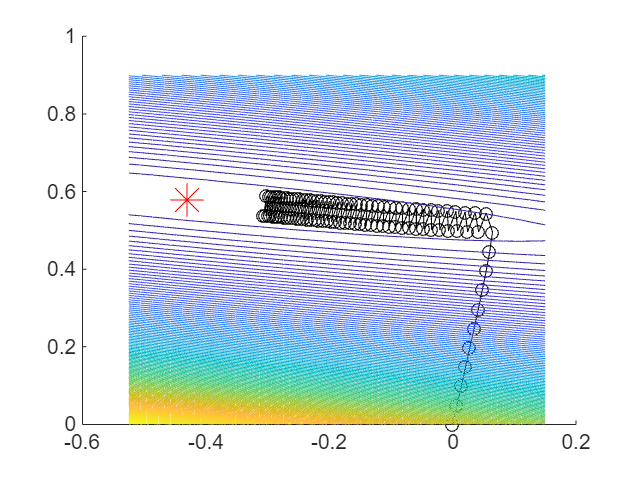

hold(ax,"off");

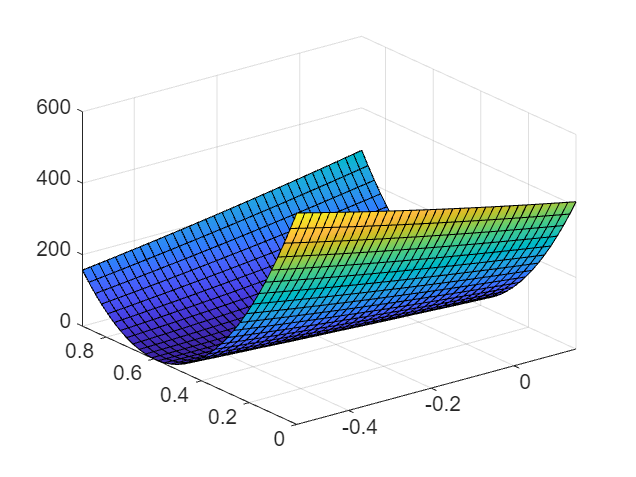

    fsurf(F_inter,[1.5*x_lim,1.5*y_lim])

[xval,fval,iternumber,outflag]=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",0.1,"N",5000)

xval =    -0.3553
    1.0769


fval = 432.4387

iternumber = 5000

outflag = 1×3 logical array
   1   1   1


disp("Ошибка фиттинга:" + string(norm(x_true-xval)))

Ошибка фиттинга:0.50249


% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.388;
[xval,~,~,~,search_history]=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",mu,"N",100)

xval =    -0.5047
    0.0831


search_history =          0    0.0721   -0.4269   -0.3558   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669   -0.4300   -0.5047   -0.4300    0.0669
         0    0.5045    0.5759    1.0733    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831    0.5800    0.5053    0.5800    0.0831  

% построим анимацию шагов работы алгоритма
ax = get_next_ax();

fig1


animated_Line = animatedline(ax,'Marker',"o",'LineStyle',"-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.01)
end
% построим контурное изображение функции невязки (чтобы убедиться что
% градиент перпендикулярен линиям постоянного уровня)
x_lim = ax.XLim;
y_lim = ax.YLim;
Nx = 10;Ny = 10;
x_grid = linspace(x_lim(1),x_lim(2),Nx);
y_grid = linspace(y_lim(1),y_lim(2),Ny);
[X,Y] = meshgrid(x_grid,y_grid);

F = @(x1,x2) residual_function([x1;x2])'*residual_function([x1;x2])/2

F = function_handle with value:
    @(x1,x2)residual_function([x1;x2])'*residual_function([x1;x2])/2




hold(ax,"on");
    plot(x_true(1),x_true(2),"r*","MarkerSize",16);
    fcontour(ax,F,[1.5*x_lim,1.5*y_lim],"LevelStep",5); % контурное изображение показывает линии постоянного значения 

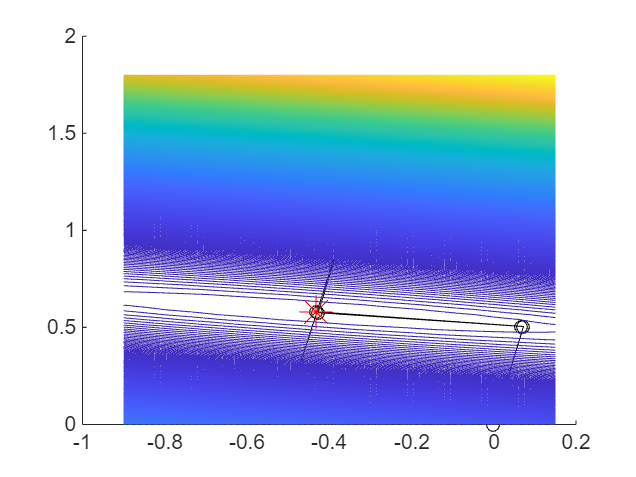

hold(ax,"off");

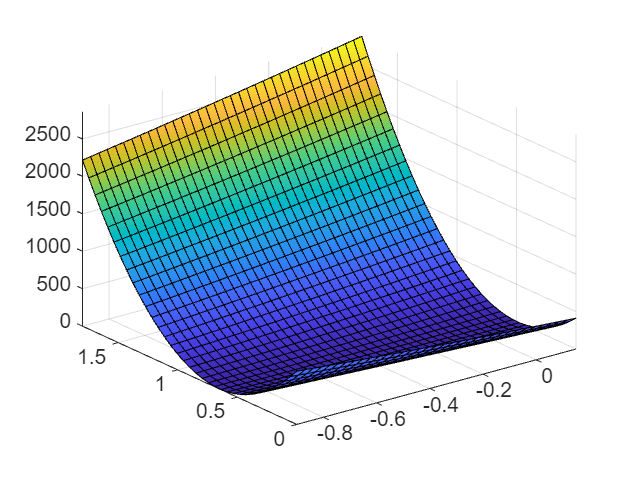

    fsurf(F,[1.5*x_lim,1.5*y_lim])

tic
    xval=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",0.01,"N",1000)
toc
tic;
    xval=grad_lsqr_linesearch([0.0; 0.0],residual_function,Jacobian,"mu",0.01,"N",1000)
toc
tic
    xval = [ones(length(t),1),t]\y
toc

## Семинар 15. Метод Гаусса-Ньютона

## Семинар 14. Ridge regression  (метод регуляризации Тихонова) и метод Левенберга-Марквардта

%{
Ridge regression produces a biased estimator of the parameters
compared to a simple linear regression, but biased estimators
are not always a bad thing.
%}
% Build some random data
clearvars
n = 10;
x = randn(n,2);
y = sum(x,2) + randn(n,1);

% the coefficients of the regression model should be [1 1]',
% since we formed y by summing the columns of x, then adding
% noise to the result.
coef = x\y

% if we generated many sets of data, we would see that with
% few data points in each set and a large noise component,
% our estimates of the parameters are fairly volatile. Don't
% forget, the nominal coefficients were [1 1]'.
coef = zeros(10,2);
for i = 1:10
  y = sum(x,2) + randn(n,1);
  coef(i,:) = (x\y)';
end
coef

% Traditional ridge regression can be viewed & accomplished
% in several ways. The pure linear regression is designed to
% minimize the quadratic form (A*coef - y)'*(A*coef - y).
% That is, it minimizes the sum of squares of the residuals
% (A*coef - y). A ridge regression simply adds a term to that
% objective: lambda*sum(coef.^2). Clearly when lambda is large,
% the coefficient vector (coef) will be biased towards zero.
% For small lambda, the ridge estimates will be largely
% unchanged from the simple linear regression.
%
% There are two simple ways to accomplish this ridge regression.
% The first is to use the normal equations. Recall that the
% normal equations (to solve the system A*coef = y) are simply:
%
%  coef = inv(A'*A)*A'*y
%
% The associated ridge estimates for a given value of lambda
% are (for p parameters to estimate, in our example, p = 2.)
%
%  coef = inv(A'*A + lambda^2*eye(p,p))*A'*y
%
% We can even think of the simple linear regression as a ridge
% estimate with lambda = 0.
%
% As before, we never want to actually use the normal equations.
% We can use \ or any other solver to accomplish this by
% augmenting the matrix A.
%
%  coef = [A;lambda*eye(p,p)] \ [y;zeros(p,1)]
%
% One way to interpret this expression is as if we had added
% extra data points, each of which implies that one of the
% parameters in the regression be zero. We can then think of
% lambda as a weight for each of those new "data" points.

p = 2;
lambda = 1;
coef = zeros(10,4);
for i = 1:10
  y = sum(x,2) + randn(n,1);
  coef(i,1:2) = (x\y)';
  coef(i,3:4) = ([x;lambda*eye(p,p)]\[y;zeros(p,1)])';
end

% The first two columns of coef are the standard regression
% estimates. Columns 3 and 4 are ridge estimates. Note that
% the ridge estimates are always biased towards zero. Had
% we used a larger value of lambda, the bias would be more
% pronounced.
coef

% Simple ridge estimators rarely seem useful to me. The type
% of bias (always towards zero) that they produce is often
% not that helpful.
%
% There are other variations on the ridge estimator that can
% be quite helpful however. To show this, we will build a
% simple spline model - a piecewise constant model. Start
% out, as always, with some data.
n = 50;
x = sort(rand(n,1));
y = sin(pi*x) + randn(size(x))/20;

close
plot(x,y,'o')
title 'Data from a trig function'

% Choose some knots
knots = 0:.01:1;
% p is the number of parameters we will estimate
p = length(knots);

% Build the regression problem - the least squares spline.
% Define the spline in terms of its value in a given knot
% interval. There are 50 data points and 101 knots. We need
% to know which knot interval every point falls in. Histc
% tells us that. (Old versions of matlab which do not have
% histc can find bindex from the file exchange.)
[junk,bind] = histc(x,knots);
% Build the matrix as a sparse one! It is sparse, so use
% that fact to our advantage.
A = sparse((1:n)',bind,1,n,p);

% solve for the least squares spline. Remember that we
% had 101 knots, so 101 parameters to estimate.
spl_coef = A\y

plot(x,y,'go',[knots(1:(end-1));knots(2:end)], ...
  repmat(spl_coef(1:(end-1))',2,1),'r-')
axis([0 1 -.2 1.2])
title 'Unregularized zero order "spline" model'
xlabel 'x'
ylabel 'y'

% When we looked at the coefficients for this spline, we should
% have seen many coefficients that were zero. More than 1/2 of
% them were zero in fact. Where there was no data, there the
% spline was estimated as zero. There was also a warning of
% "rank deficiency". Since there were only 50 data points, but
% 101 knots (therefore 101 parameters to estimate) this was
% expected.
%
% We can improve this dramatically with the use of a ridge
% regression. Here I'll set up the bias so that each parameter
% is biased to be close to its neighbors in the spline.
B = spdiags(ones(p-1,1)*[-1 1],[0 1],p-1,p);

% Solve. Try it with a reasonably small lambda.
lambda = 1e-3;
spl_coef_r = ([A;lambda*B]\[y;zeros(p-1,1)])
% This time, no zero coefficients, and no rank problems.

plot(x,y,'go',[knots(1:(end-1));knots(2:end)], ...
  repmat(spl_coef_r(1:(end-1))',2,1),'r-')
title 'Zero order spline model with minimal regularization'
xlabel 'x'
ylabel 'y'

% This least squares spline, with only a tiny amount of a bias,
% looks quit reasonable. The trick is that the regularization
% term is only significant for those knots where there is no data
% at all to estimate the spline. The information for those spline
% coefficients is provided entirely by the regularizer.

% We can make lambda larger. Try varying lambda in this block
% of code on your own. You will see that lambda = 1 yields just
% a bit more smoothing. Lambda = 10 or 100 begins to seriously
% bias the result not towards zero, but to the overall mean of
% the data!

% There are other ways to do this regularization. We might also
% choose to bias the integral of the second derivative of the
% curve (for higher order splines.)

% There is one more question to think about when doing any
% regularized regression: What is the correct value for lambda?
%
% Too small or too large, either is not good. In the middle is
% just right. But where is Goldilocks when you need her?
%
% An answer can sometimes be found in cross validation.
% This entails repeated fits, dropping out each data point in
% turn from the fit, then predicting the dropped point from the
% model. The ridge parameter (lambda) which results in the lowest
% overall prediction error sum of squares is the choice to use.

% A nice discussion of cross validation in its many forms can
% be found here:
% http://www.quantlet.com/mdstat/scripts/csa/html/node123.html

% I'll show an example of ordinary cross validation (OCV) in
% action for the same spline fit. First, we'll plot the prediction
% error sums of squares (PRESS) as a function of lambda.

nl = 21;
lambda = logspace(-1,2,nl);
press = zeros(1,nl);
% loop over lambda values for the plot
for i = 1:nl
  k = 1:n;
  % loop over data points, dropping each out in turn
  for j = 1:n
    % k_j is the list of data points, less the j'th point
    k_j = setdiff(k,j);

    % fit the reduced problem
    spl_coef = ([A(k_j,:);lambda(i)*B]\[y(k_j);zeros(p-1,1)]);

    % prediction at the point dropped out
    pred_j = A(j,:)*spl_coef;
    % accumulate press for this lambda
    press(i) = press(i) + (pred_j - y(j)).^2;
  end
end
% plot, using a log axis for x
semilogx(lambda,press,'-o')
title 'The "optimal" lambda minimizes PRESS'
xlabel 'Lambda'
ylabel 'PRESS'
% Note: there is a minimum in this function near lambda == 1,
% although it is only a slight dip. We could now use fminbnd
% to minimize PRESS(lambda).

% I'll be lazy here, and guess from the plot that PRESS was
% minimized roughly around lambda == 2.
lambda = 2;
spl_coef_r = ([A;lambda*B]\[y;zeros(p-1,1)]);
% This time, no zero coefficients, and no rank problems.

plot(x,y,'go',[knots(1:(end-1));knots(2:end)], ...
  repmat(spl_coef_r(1:(end-1))',2,1),'r-')
title 'Zero order spline model with lambda == 2'
xlabel 'x'
ylabel 'y'

ДАЛЬШЕ ИДЕТ БЛОК ФУНКЦИЙ

function folder = get_folder()
% функция смотрит какой файл открыт в редакторе в настоящий момент и
% возвращает путь к данному файлу
    folder = fileparts(matlab.desktop.editor.getActiveFilename);
end

function [y,p] = persistent_func(f,dx)
% функция сдвигает фазу аргумента функции f на величину dx
    persistent x
    persistent animated_Line axes_handle; % при первом пуске persistent переменная []
    if isempty(x)
        x =-dx; % обнуляем сдвиг в начальный момент
    end
    if isempty(animated_Line)
        axes_handle = axes(figure(10),"XTickMode","manual","YTickMode","manual","XLim",[0,2*pi],"YLim",[-1 1]);
        animated_Line = animatedline(axes_handle,"Marker","o","LineStyle","none");
    end
    x=x+dx;
    y = f(x);
    addpoints(animated_Line,x,y);
    drawnow  
end

function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end